# **TP2 : Suite de l'introduction à l'automatique sur Matlab**

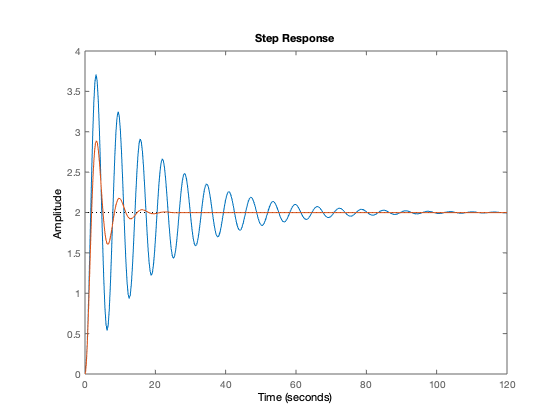

s = tf('s');
G = 2 / (s ^ 2 + 0.1 * s + 1 );
G1 = 2 / (s^2 + 0.5 * s + 1);
step(G, G1)

Avec un clic droit dans la fenetre de la figure, sous 

Omega => Pulsation propre du système

Xi => Coefficiant d'amortissement

## Pulsation propre (omega) et coefficiant d'amortissement (Xhi)

La Pulsation naturelle est la pulsation si l'on avait pas de coefficiant s (frequence d'ocillement)

[omega, xi] = damp(G)

omega =      1
     1


xi =     0.0500
    0.0500


[omega1, xi1] = damp(G1)

omega1 =      1
     1


xi1 =     0.2500
    0.2500


Coefficiant d'amortissement plus grand = atténuation plus rpapde. Plus coéfficient est élevé plus la fonction va osciller

## Gain statique 

dcgain(G)

ans = 2

dcgain(G1)

ans = 2

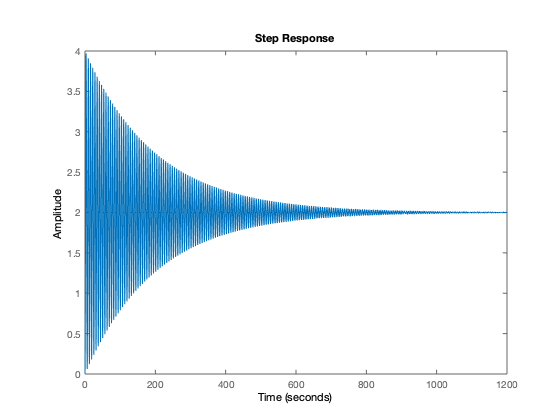

G3 = 2 / (s^2 + 0.01 * s + 1);
step(G3)

## Tracer les zéros et les poles

La valeur est plus réelle est beaucoup plus faible que la valeur imaginaire : oscillation plus importante. Si la valeur est imaginaire pure, alors c'est une oscilation pure 

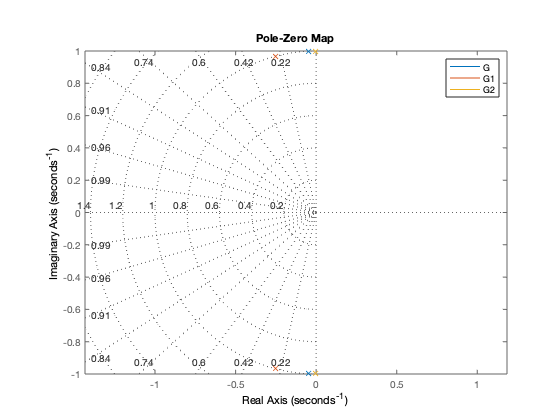

pzmap(G,G1,G3)
legend('G', 'G1', 'G2')
grid
axis('equal')

On peut faire apparaitre certaines fonctions particulières de l'espace avec grid.

L'ajout de axis('equals') permet de forcer l'égalité des axes

Les 3 fonctions de transferts ont la même pulsation prpre : elles sont sur le même rayon qui correspond à Omega 0 

On peut donc lire directement la valeu de oméga 0 sur le cercke. Quand omega0 esst constant, les racines se baladent sur le demis cercke. 

Sur les secteurs, on peut retrouver xhi.

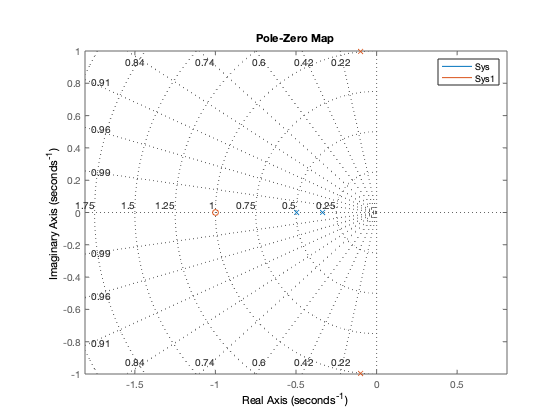

T1 = 3;
T2 = 2;
Sys = 2 / ((1 + s * T1) * (1 + s * T2));
Sys1 = 2 * (s + 1) / (s^2 + 0.2 * s + 1);
SysP = Sys * Sys1 / (1+ Sys * Sys1);

pzmap(Sys, Sys1)
grid
axis('equal')
legend('Sys', 'Sys1')

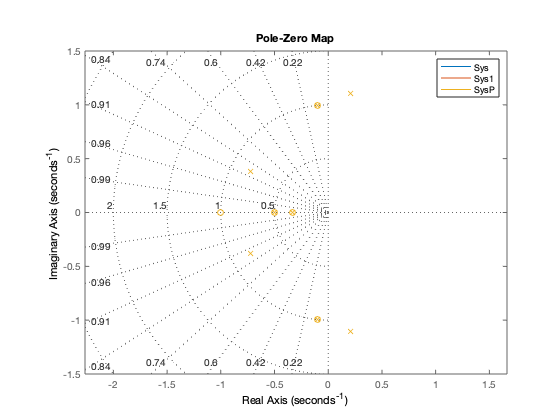

pzmap(Sys, Sys1, SysP)
grid
axis('equal')
legend('Sys', 'Sys1', 'SysP')

Les **ronds** représentent les zéros et les **croix** représentent les pôles

On eut voir à certrains que certains zéros sont aussi des pôles : cela veut dire que l'on aura (s+a) au numérateur et au dénominateur. Naturellement, lorsque l'on fait le calcul, on simplifie. Cela veut dire que la forme que l'on obtient n'est pas la forme nulle. Elle peut se simplifier si l'on retire les poles et le zeros.

La fonction de transfert est d'ordre 6.

## Fonction de transfert minimale

minreal(SysP)


ans =
 
                0.6667 s + 0.6667
  ----------------------------------------------
  s^4 + 1.033 s^3 + 1.333 s^2 + 1.533 s + 0.8333
 
Continuous-time transfer function.



un pôle à une partie réelle négative : Le système est instable --> On ne peut pas le controller.

Pour le rendre commendable, il faut le mettre en boucle fermée, pour le stabiliser avec le correcteur.

C'est pseudo-oscillant à cause de la partie imaginaire. Avec des pôles instables purement réels; il n'y aura pas d'oscillations.

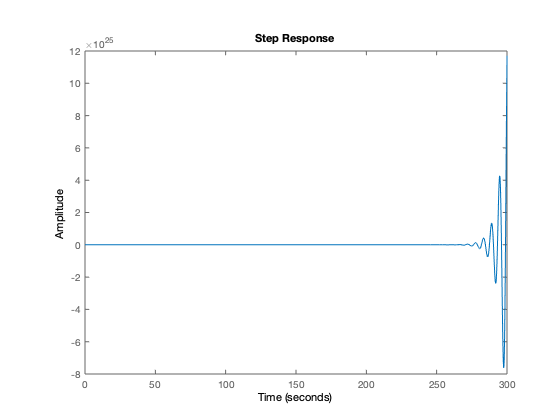

step(minreal(SysP))

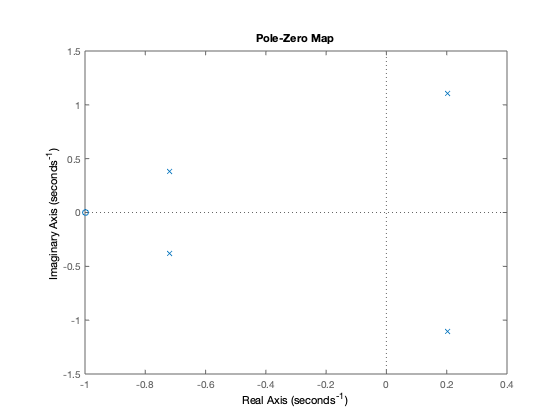

p

zmap(minreal(SysP))

## Décomposition en élément symple

Donne les valeurs des alpha/(1+s*T1), beta/(1+s*T2), ... (pour faire une décomposition en élément symple)

residue(Sys.num{1}, Sys.den{1})

ans =    -2.0000
    2.0000
